%%%%%%%%%%%%%%%%%%%%%%
%%%import data
%%%%%%%%%%%%%%%%%%%%%%

%% find current working folder
fp = fileparts(matlab.desktop.editor.getActiveFilename);
cd(fp) %% change to code folder
cd ../../Data/Processed/EtO/'Data Conversions' %change to data folder

%%ppb data, including data with all flags
%SDK
ppbSDK = readtimetable("ppb SDK.xlsx", "Sheet", "base", "VariableNamingRule", "preserve");
ppbSDKnoLK = readtimetable("ppb SDK.xlsx", "Sheet", "base no LK", "VariableNamingRule", "preserve");
ppbSDKnoHg = readtimetable("ppb SDK.xlsx", "Sheet", "base no 0 Hg", "VariableNamingRule", "preserve");
ppbSDKATEC = readtimetable("ppb SDK.xlsx", "Sheet", "ATEC", "VariableNamingRule", "preserve");
ppbSDKATECnoLK = readtimetable("ppb SDK.xlsx", "Sheet", "ATEC no LK", "VariableNamingRule", "preserve");
ppbSDKATECnoHg = readtimetable("ppb SDK.xlsx", "Sheet", "ATEC no 0 Hg", "VariableNamingRule", "preserve");
ppbSDKEnt = readtimetable("ppb SDK.xlsx", "Sheet", "Ent", "VariableNamingRule", "preserve");
ppbSDKEntnoLK = readtimetable("ppb SDK.xlsx", "Sheet", "Ent no LK", "VariableNamingRule", "preserve");
ppbSDKEntnoHg = readtimetable("ppb SDK.xlsx", "Sheet", "Ent no 0 Hg", "VariableNamingRule", "preserve");
ppbSDKPicarro = readtimetable("ppb SDK.xlsx", "Sheet", "Picarro", "VariableNamingRule", "preserve");

%STER
ppbSTER = readtimetable("ppb STER.xlsx", "Sheet", "base", "VariableNamingRule", "preserve");
ppbSTERnoLK = readtimetable("ppb STER.xlsx", "Sheet", "base no LK", "VariableNamingRule", "preserve");
ppbSTERnoHg = readtimetable("ppb STER.xlsx", "Sheet", "base no 0 Hg", "VariableNamingRule", "preserve");

%SSG
ppbSSG = readtimetable("ppb SSG.xlsx", "Sheet", "base", "VariableNamingRule", "preserve");
ppbSSGnoLK = readtimetable("ppb SSG.xlsx", "Sheet", "base no LK", "VariableNamingRule", "preserve");
ppbSSGnoHg = readtimetable("ppb SSG.xlsx", "Sheet", "base no 0 Hg", "VariableNamingRule", "preserve");

%COV
ppbCOV = readtimetable("ppb COV.xlsx", "Sheet", "base", "VariableNamingRule", "preserve");
ppbCOVnoLK = readtimetable("ppb COV.xlsx", "Sheet", "base no LK", "VariableNamingRule", "preserve");
ppbCOVnoHg = readtimetable("ppb COV.xlsx", "Sheet", "base no 0 Hg", "VariableNamingRule", "preserve");

cd ..

%SDK AROMA
ppbSDKAROMA = readtimetable("etoAROMA_SDK.xlsx");

%Houston
ppbHouAROMA = readtimetable("etoAROMA_houston.xlsx"); %AROMA
ppbHouEnt = readtimetable("TO15_houston.xlsx"); %TO-15

%%receptors
points = readtable("mapPoints.xlsx", "sheet", "From Matlab"); %grab receptor data

%%met data
cd ../Met

%% continuous data for CRDS
rawMetSDK = readtimetable("Met_SDK.xlsx"); %SDK data 8/19-8/22
rawMetHou = readtimetable("Met_houston.xlsx"); %Houston 9/22

%% data already averaged to canisters
rawMetSDKtoCan = readtimetable("Met_SDK.xlsx", ...
    "Sheet", "avg to can days"); %SDK data 8/19-8/22
rawMetSTERtoCan = readtimetable("Met_STER.xlsx", ...
    "Sheet", "avg to can days"); %STER 8/19-7/22
rawMetSSGtoCan = readtimetable("Met_SSG.xlsx", ...
    "Sheet", "avg to can days"); %STER 8/19-7/22
rawMetCOVtoCan = readtimetable("Met_COV.xlsx", ...
    "Sheet", "avg to can days"); %STER 8/19-7/22

cd ../.. %return to data folder

%%%%%%%%%%%%%%%%%%%%%%
%%%calculate temperature/other dependence
%%%%%%%%%%%%%%%%%%%%%%

%%%INPUTS, change to change flagged data
dataSDKEnt = ppbSDKEnt; 
dataSDKATEC = ppbSDKATEC;
dataSDKPicarro = ppbSDKPicarro;
dataSDKAROMA = ppbSDKAROMA(:, 2); %take start date as averaging met; reasonable
dataSTER = ppbSTER;
dataSSG = ppbSSG;
dataCOV = ppbCOV;
dataHouAROMA = ppbHouAROMA(:, 2);
dataHouEnt = ppbHouEnt;
time = dataSDKEnt.time;
timeStart = time(1);
timeEnd = time(end);

%for averaging
daysNeeded = dateshift(time, 'start', 'day'); %beginning of each day needed, exclude first row
% timeBounds = hours([11, 14]); %beginning and end times wanted for average
timeBounds = hours([0, 23.999]);

%for Picarro specifically
daysNeededPicarro = datetime(2021, [8, 12], [7, 10]); %aug 7 to dec 10, 2021
daysNeededPicarro = daysNeededPicarro(1):days(1):daysNeededPicarro(2); %every day
timeBoundsPicarro = hours([0, 23.999]);
% timeBoundsPicarro = timeBounds;

%for finding the dependence on met
% metVarWanted = "T"; %amb temp
metVarWanted = "HUMID"; %humidity

%%%time shift all data inputs
dataSDKEnt.Properties.RowTimes = dateshift(dataSDKEnt.Properties.RowTimes, "start", "day");
dataSDKATEC.Properties.RowTimes = dateshift(dataSDKATEC.Properties.RowTimes, "start", "day");
dataSTER.Properties.RowTimes = dateshift(dataSTER.Properties.RowTimes, "start", "day");
dataSSG.Properties.RowTimes = dateshift(dataSSG.Properties.RowTimes, "start", "day");
dataCOV.Properties.RowTimes = dateshift(dataCOV.Properties.RowTimes, "start", "day");

rawMetSDKtoCan.Properties.RowTimes = dateshift(rawMetSDKtoCan.Properties.RowTimes, "start", "day");
rawMetSTERtoCan.Properties.RowTimes = dateshift(rawMetSTERtoCan.Properties.RowTimes, "start", "day");
rawMetSSGtoCan.Properties.RowTimes = dateshift(rawMetSSGtoCan.Properties.RowTimes, "start", "day");
rawMetCOVtoCan.Properties.RowTimes = dateshift(rawMetCOVtoCan.Properties.RowTimes, "start", "day");

% %%%function to average met data & picarro data by weighted average
% 
% %%INPUTS
% % daysNeeded
% % timeBounds
% 
% %%average met by time for met
% [rawMetAvgSDK, rawMetStdSDK, nanPercentSDK] = averageTTbyTime(rawMetSDK, daysNeeded, timeBounds); %SDK
% [rawMetAvgSTER, rawMetStdSTER, nanPercentSTER] = averageTTbyTime(rawMetSTER, daysNeeded, timeBounds); %STER
% [rawMetAvgSSG, rawMetStdSSG, nanPercentSSG] = averageTTbyTime(rawMetSSG, daysNeeded, timeBounds); %SSG
% [rawMetAvgCOV, rawMetStdCOV, nanPercentCOV] = averageTTbyTime(rawMetCOV, daysNeeded, timeBounds); %COV
% 
% %%average Picarro by time as well
% [allDataAvgSDKPicarro, allDataStdSDKPicarro, nanPercentSDKPicarro] = ...
%     averageTTbyTimePicarro(dataSDKPicarro, daysNeededPicarro, timeBoundsPicarro); %SDK Picarro
% [rawMetAvgSDKPicarro, rawMetStdSDKPicarro, nanPercentMetSDKPicarro] = ...
%     averageTTbyTime(rawMetSDK, daysNeededPicarro, timeBounds); %SDK
% 
% %remove nan > 20%
% inds = nanPercentSDKPicarro.Corrected_EtO > 0.2;
% sum(inds) %number of data points removed
% dataAvgSDKPicarro = allDataAvgSDKPicarro(~inds, :);
% dataStdSDKPicarro = allDataStdSDKPicarro(~inds, :);

%%%get non-exploded and exploded data
%%% exploded data meaning comparisons of each data point to the met data
%%% point
%%%[met data, measurement data, % nan, met std, measurement std (for non-exploded)]

%%INPUTS
% metVarWanted


%%get non-exploded data first
compareAvSDKEnt = getNonExplode(rawMetSDKtoCan, metVarWanted, dataSDKEnt);
compareAvSDKATEC = getNonExplode(rawMetSDKtoCan, metVarWanted, dataSDKATEC);
compareAvSTER = getNonExplode(rawMetSTERtoCan, metVarWanted, dataSTER);
compareAvSSG = getNonExplode(rawMetSSGtoCan, metVarWanted, dataSSG);
compareAvCOV = getNonExplode(rawMetCOVtoCan, metVarWanted, dataCOV);

%%for CRDS

%Picarro data in particular
inds = rawMetSDK.time >= daysNeededPicarro(1) & rawMetSDK.time <= (daysNeededPicarro(end) + days(1));
compareExSDKPicarro = rawMetSDK(inds, metVarWanted); %grab met data
compareExSDKPicarro = synchronize(compareExSDKPicarro, dataSDKPicarro); %add picarro data
compareExSDKPicarro.Properties.VariableNames = ["met", "EtO"]; %rename properly

%SDK, AROMA
times = dateshift(dataSDKAROMA.Properties.RowTimes, "start", "hour"); %match signal to top of hour met
compareExSDKAROMA = timetable(times); %initiate empty table
[~, inds] = ismember(times, rawMetSDK.Properties.RowTimes);
compareExSDKAROMA.met = rawMetSDK.(metVarWanted)(inds); %add met data
compareExSDKAROMA.EtO = dataSDKAROMA.EtO; %add eto data

%Hou, AROMA
times = dateshift(dataHouAROMA.Properties.RowTimes, "start", "hour"); %match signal to top of hour met
compareExHouAROMA = timetable(times); %initiate empty table
[~, inds] = ismember(times, rawMetHou.Properties.RowTimes);
compareExHouAROMA.met = rawMetHou.(metVarWanted)(inds); %add met data
compareExHouAROMA.EtO = dataHouAROMA.EtO; %add eto data

%%%function to return stats and linear model based on met variable

%% TO-15
mdlAvSDKEnt = fitlm(compareAvSDKEnt.met, compareAvSDKEnt.EtO);
mdlAvSDKATEC = fitlm(compareAvSDKATEC.met, compareAvSDKATEC.EtO);
mdlAvSTER = fitlm(compareAvSTER.met, compareAvSTER.EtO);
mdlAvSSG = fitlm(compareAvSSG.met, compareAvSSG.EtO);
mdlAvCOV = fitlm(compareAvCOV.met, compareAvCOV.EtO);

%% CRDS
mdlExSDKPicarro = fitlm(compareExSDKPicarro.met, compareExSDKPicarro.EtO);
mdlExSDKAROMA = fitlm(compareExSDKAROMA.met, compareExSDKAROMA.EtO); 
mdlExHouAROMA = fitlm(compareExHouAROMA.met, compareExHouAROMA.EtO); 

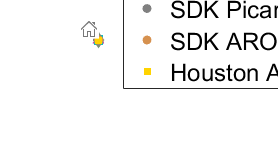

%%%%%%%%%%%%%%%%%%%%%%
%%%plot
%%%%%%%%%%%%%%%%%%%%%%
colorSTER = [0.769, 0.080, 0.557];
colorSSG = [0.071, 0.74, 0.74];
colorCOV = [122, 142, 117]/255;
colorAROMA = [0.8392, 0.5686, 0.3098];
%colors: passive, pressurized, STER, SSG, COV, picarro, AROMA SDK, AROMA Houston
colors = [1, 0, 0; 0, 0, 1; colorSTER; colorSSG; colorCOV; 0.5, 0.5, 0.5; colorAROMA; 1, 0.828, 0];
markerStyles = {'o', 'o', '^', 'square', 'diamond', 'o', 'o', 'square'};

%make allMdl
allMdl = {mdlAvSDKEnt, mdlAvSDKATEC, mdlAvSTER, mdlAvSSG, mdlAvCOV, ...
    mdlExSDKPicarro, mdlExSDKAROMA, mdlExHouAROMA};

%legend prefix
legPre = ["SDK passive, n=", "SDK pressurized, n=", "STER passive, n=", ...
    "SSG passive, n=", "COV passive, n=", "SDK Picarro, n=", "SDK AROMA, n=", "Houston AROMA, n="];

%%plot
fig = figure('Position', get(0, 'Screensize')); %for saving the figure
tiledlayout(1, 2, "tilespacing", "compact")

%%1. TO-15
ax = nexttile;
grid on
hold on
box on
pbaspect([1.4, 1, 1])

%%NOTE: I have shuffled around the plot order so things are more visible
h = gobjects(4, 5);

%plot SSG passive, SDK Pressurized, and STER, SSG, and COV passive
for i = 1:5
  
    %plot pressurized
    h(:, i) = plot(allMdl{i});
    h(1, i).Marker = markerStyles{i};
    h(1, i).MarkerSize = 6;
    if i > 3, h(1, i).MarkerSize = 7.5; end %for the sqaure
    h(1, i).MarkerEdgeColor = colors(i, :);
    h(1, i).MarkerFaceColor = colors(i, :);
    h(2, i).Visible = "off";
    h(3, i).Visible = "off"; %bounding line
    h(4, i).Visible = "off";
    temp = corr(table2array(allMdl{i}.Variables), 'rows','complete');
    corrs(i) = temp(1, 2);
    ns(i) = length(allMdl{i}.Fitted);
end

% %axis limits
xlim([0, 25])
ylim([-0.05, 2.5]) %truncates one point at around 4.15 for STER
yticks(0:0.5:2.5)

%labels
ax.FontSize = 20;
xlabel("Specific Humidity (g H_2O/kg air)", "Interpreter", "tex")
ylabel("EtO (ppb)")
title("")
%get legend in order I want
leg1 = gobjects(1, 5);
leg1(1, 1) = h(1, 1); %SDK passive 
leg1(1, 2) = h(1, 2); %SDK, pressurized
leg1(1, 3) = h(1, 3); %STER
leg1(1, 4) = h(1, 4); %SSG
leg1(1, 5) = h(1, 5); %COV 
legStr = [""];
for i = 1:5
    legStr(i) = strcat(legPre(i), num2str(ns(i)), ", r=",sprintf("%0.2f", corrs(i)));
end
ax.Legend.Visible = 'off'; % turn mdl legend off
hold off


%%2. CRDS
ax = nexttile;
grid on
hold on
box on
pbaspect([1.4, 1, 1])

%%NOTE: I have shuffled around the plot order so things are more visible
h = gobjects(4, 3);

%plot SSG passive, SDK Pressurized, and SDK Picarro 
for i = 6:8
  
    %plot pressurized
    h(:, i-5) = plot(allMdl{i});
    h(1, i-5).Marker = markerStyles{i};
    h(1, i-5).MarkerSize = 6;
    if i == 8, h(1, i-5).MarkerSize = 7; end
    h(1, i-5).MarkerEdgeColor = colors(i, :);
    h(1, i-5).MarkerFaceColor = colors(i, :);
    h(2, i-5).Visible = "off";
    h(3, i-5).Visible = "off"; %bounding line
    h(4, i-5).Visible = "off";
    temp = corr(table2array(allMdl{i}.Variables), 'rows','complete');
    corrs(i) = temp(1, 2);
    ns(i) = length(allMdl{i}.Fitted);
end

% %axis limits
xlim([0, 30])
ylim([-0.15, 0.3]) %truncates 3 points for Picarro
yticks(-0.1:0.1:0.3)

%labels
ax.FontSize = 20;
xlabel("Specific Humidity (g H_2O/kg air)", "Interpreter", "tex")
ylabel("EtO (ppb)")
title("")
%get legend in order I want
leg2 = gobjects(1, 3);
leg2(1, 1) = h(1, 1); %SDK, Picarro
leg2(1, 2) = h(1, 2); %SDK, AROMA
leg2(1, 3) = h(1, 3); %Houston, AROMA
for i = 6:8
    legStr(i) = strcat(legPre(i), num2str(ns(i)), ", r=",sprintf("%0.2f", corrs(i)));
end
ax.Legend.Visible = 'off'; % turn mdl legend off
hold off

hL = legend(leg2, legStr(6:8));
hL.Layout.Tile = 'East';

% cd ..\Figures
% a = annotation('rectangle',[0 0 1 1],'Color','w'); %add padding
% fn = "Sup humidity.png";
% exportgraphics(fig, fn)
% delete(a) %make plot interactive again

% cd ..\Data

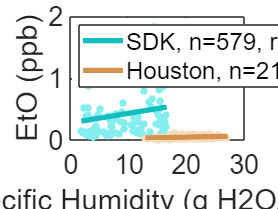

%%testing ground for models
figure
ax = gca;
hold on
box on
pbaspect([1.4, 1, 1])

h = gobjects(4, 2);

for i = [4, 7] %AROMA SDK and AROMA Houston
    h(:, i) = plot(allMdl{i});
    h(1, i).Marker = "o";
    h(1, i).MarkerSize = 5;
    h(1, i).MarkerEdgeColor = sqrt(sqrt(colors(i, :)));
    h(1, i).MarkerFaceColor = sqrt(sqrt(colors(i, :)));
    h(2, i).Color = colors(i, :);
    h(2, i).LineWidth = 4;
    h(3, i).Visible = "off"; %bounding line
    h(4, i).Visible = "off";
    uistack(h(2, i), "top")
end

xlim([0, 30])
ax.FontSize = 20;
ylabel("EtO (ppb)")
xlabel("Specific Humidity (g H2O/kg air)")
title("")
temp = gobjects(2, 1);
temp(1) = h(2, 1);
temp(2) = h(2, 2);
legend("", "", "", "SDK, n=579, r=0.35", ... %slope is 0.002
    "", "", "", "Houston, n=215, r=-0.30",... %slope is -0.0008
    "location", "northwest")
hold off

function [TT] = getNonExplode(rawMetAv, metVarWanted, data)
%%% prepares non-exploded timetable ready for processing

%%fixed inputs
varNames = ["met", "EtO", "EtOstd"];

outTTAvSame = avSameTime(array2timetable(rawMetAv.(metVarWanted), 'RowTimes', rawMetAv.Properties.RowTimes), ...
    data); % [met, EtO]
TT = timetable(outTTAvSame.time, outTTAvSame.avg1, outTTAvSame.avg2, ...
    outTTAvSame.std2); %SDK passive
TT.Properties.VariableNames = varNames;
TT.Properties.DimensionNames(1) = "time";
end

function [mdl, stats] = makeLinMdl(data)
%%%makes a model of data from compiled comparison table for met and data

%%make model
mdl = fitlm(data.met, data.EtO);

%%populate stats
stats = table();
stats.n = sum(~isnan(table2array(mdl.Residuals(:, 1))));
stats.r = corr(data.met, data.EtO, "rows", "complete");
stats.intercept = table2array(mdl.Coefficients(1, 1));
stats.slope = table2array(mdl.Coefficients(2, 1));
end

function [averagedData, stdevData, nanPercent] = averageTTbyTimePicarro(raw, daysNeeded, timeBounds)
%%%calculates average, standard dev, and percent nan for the data in timetable raw for the
%%%days needed between the timebounds, inclusive. Assumes data reported on
%%%a line is for the average between that point and the next
%raw is a timetable of doubles
%daysNeeded is an array of datetime days where data are needed to average
%timeBounds is a two-member array of durations from 0000 between which data
%are averaged each day

%%preformatting
averagedData = raw; %replicate structure of rawMet and replace with nan
averagedData(length(daysNeeded)+1:end, :) = [];
averagedData.Properties.RowTimes = daysNeeded; %format times to format necessary
temp = timetable2array(averagedData)*nan;
averagedData(:, :) = array2timetable(temp, "RowTimes", daysNeeded); %set all data to nan
stdevData = averagedData; %have stdevData replicate this as well
nanPercent = averagedData; %have nanPercent replicate this as well
times = raw.Properties.RowTimes; %grab the met data times

for i = 1:length(daysNeeded)
    %filter for time needed
    timeStart = daysNeeded(i) + timeBounds(1); %start time is day of + beginning duration
    timeEnd = daysNeeded(i) + timeBounds(end); %end time is day of + ending duration
    inds = find(isbetween(times, timeStart, timeEnd)); %grab met times between
    if ~isempty(inds) %make sure there are values
        inds = [inds(1) - 1; inds]; %grab time step before beginning of period as well
        %grab needed data in the time step
        rawNeeded = timetable2array(raw(inds, :));
        timesNeeded = times(inds);

        %calculate difference in times
        temp = [timeStart; timesNeeded(2:end); timeEnd]; %cap beginning and end times
        timeDiff = diff(temp);
        timeDiff = minutes(timeDiff); %convert to minutes

        %calculate nan percent
        nanPerc = timeDiff'*isnan(rawNeeded); %total number of nans
        nanPerc = nanPerc/sum(timeDiff); %percent of total nan
        nanPercent(i, :) = array2timetable(nanPerc, "RowTimes", daysNeeded(i));

        inds = isnan(rawNeeded); %REMOVE NAN
        rawNeeded(inds) = [];
        timeDiff(inds) = [];

        %calculate weighted average of necessary times
        avg = timeDiff'*rawNeeded; %weighted element sum
        avg = avg/sum(timeDiff); %mean of each element
        averagedData(i, :) = array2timetable(avg, "RowTimes", daysNeeded(i));

        %calculate weighted std of necessary times
        rawDiff = rawNeeded - avg; %observation differences
        rawDiff = rawDiff.^2; %observation differences squared
        sd = timeDiff'*rawDiff; %weighted element sqare diff sum
        M = sum(timeDiff ~= 0); %number non-zero weights
        sd = sqrt(sd*M/(M-1)/sum(timeDiff)); %weighted std
        stdevData(i, :) = array2timetable(sd, "RowTimes", daysNeeded(i));
    else
        temp = ones([1, size(raw, 2)]); %if missing data, all are nan
        nanPercent(i, :) = array2timetable(temp, "RowTimes", daysNeeded(i));
    end
end

end